**WILL TIRONE **

**LAB 4 MAT 343**

**QUESTION 1**

type VerticalShear.m

clf 
S=[0,1,1,0,0;0,0,1,1,0]; 
plot(S(1,:),S(2,:),'linewidth',2) 
hold on 
T=[1,0;2,1];   
TS=T*S; 
plot(TS(1,:),TS(2,:),'-r','linewidth',2); 
title('Example of vertical shear by 2 units') 
legend('original square','sheared square','location','southeast') 
axis equal,axis([-1,4,-1,4]); grid on   
hold off


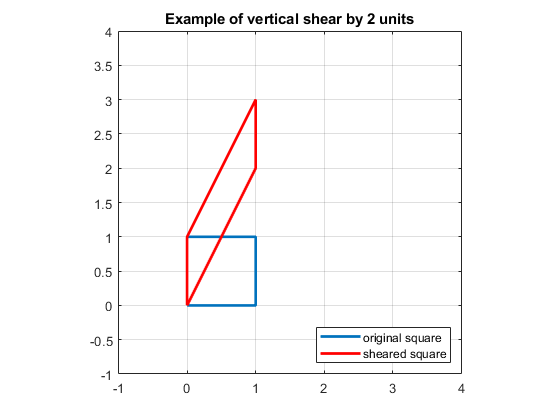

VerticalShear

**QUESTION 2**

**Are the results the same?Does the order of the transformations matter? **No, the results are not the same and the order does matter. As displayed below, this is different than EXAMPLE 4 in the lab guide. In general, AB =/= BA in linear algebra and this makes sense below. If a sheared image is rotated, it will be different than rotating THEN shearing. 

type ShearAndRotate.m

%apply the shear and then rotate 

clf 
S=[0,1,1,0,0;0,0,1,1,0]; 
plot(S(1,:),S(2,:),'linewidth',2) 
hold on 

theta = pi / 6;
Q=[ cos( theta ),-sin( theta ); sin( theta ),cos( theta )];
T =[1 ,4;0 ,1]; %shear matrix

QTS=Q*T*S; 
plot(QTS(1,:),QTS(2,:),'-r','linewidth',2); 

title('Example of horizontal shear and rotate') 
legend('original square','sheared square','location','southeast') 
axis equal,axis([-1,4,-1,4]); grid on   
hold off


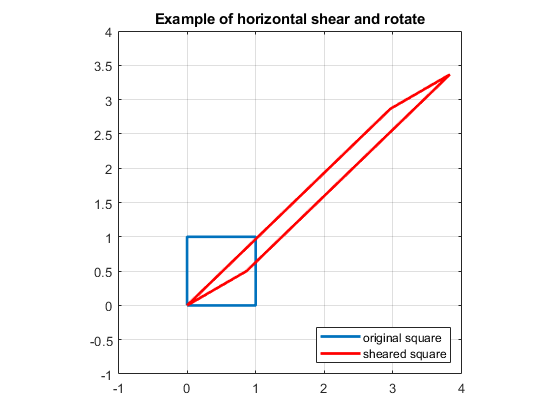

ShearAndRotate

**QUESTION 3**

type pi_over_eight_rotation.m

clf                               % clear all settings for the plot
S=[0,1,1,0,0;0,0,1,1,0];
theta =pi /8; % define the angle
Q=[cos( theta ), -sin( theta ); sin( theta ), cos( theta)];  
p = plot(S(1,:),S(2,:));          % plot the square
axis([-1,4,-1,4])                 % set size of the graph
axis square, grid on              % make the display square
hold on                           % hold the current graph
for i = 1:16
    S = Q*S;                               % dilate the square
    set(p,'xdata',S(1,:),'ydata',S(2,:));   % erase original figure and plot
                                            % the transformed figure
    pause(0.1)         % adjust this pause rate to suit your computer.
end

neg_Q=[cos(-theta ), -sin(-theta ); sin(-theta ), cos(-theta)];  

for i = 1:16
    S = neg_Q*S;                               % contract the square
    set(p,'xdata',S(1,:),'ydata',S(2,:));   % erase original figure and plot
                                            % the transform

**QUESTION 4**

type ExpandAndRotate.m

clf                               % clear all settings for the plot
S=[0,1,1,0,0;0,0,1,1,0];
D1 = 9/8* eye (2);
theta =pi /8; % define the angle
Q=[cos( theta ), -sin( theta ); sin( theta ), cos( theta)];  
p = plot(S(1,:),S(2,:));          % plot the square
axis([-8,8,-8,8]);                % set size of the graph
axis square, grid on              % make the display square
hold on                           % hold the current graph

for i = 1:16
    S = D1*Q*S;                               % dilate the square
    set(p,'xdata',S(1,:),'ydata',S(2,:));   % erase original figure and plot
                                            % the transformed figure
    pause(0.1)         % adjust this pause rate to suit your computer.
end

neg_Q=[cos(-theta ), -sin(-theta ); sin(-theta ), cos(-theta)];  
D2 = 8/9* eye (2);

for i = 1:16
    S = D2*neg_Q*S;                               % contract the square
    set(p,'xdata',S(1,:),'ydata',S(2,:));   % erase original figure and plot
              

**QUESTION 5**

type TransateAndReflect.m

clf 
S=[0,1,1,0,0;0,0,1,1,0;1,1,1,1,1];    % square in homogeneous coordinates 
M=[1,0,2;0,1,-1;0,0,1];     % translation matrix 
R=[0 1 0; 1 0 0; 0 0 1]; % reflection across 45 degrees 

MS=M*S;    
plot(MS(1,:),MS(2,:),'k','linewidth',2); 
hold on 

RS=R*MS;     
plot(RS(1,:),RS(2,:),'r','linewidth',2); 

plot([-2,4],[-2,4]); 
legend('translated square','reflected square','line y = x','location','southwest');   
axis equal, axis([-2,4,-2,4]), grid on    % adjust the axis 
hold off


**QUESTION 6**

type Example8Modified.m

clf 
S=[0,1,1,0,0;0,0,1,1,0;1,1,1,1,1]; %  square in homogeneous coordinates 

M1 = [1,0,0.4;0,1,0;0,0,1]; %  first translation matrix 
M2 = [1,0,0;0,1,0.4;0,0,1]; %  the second translation matrix 
M3 = [1 0 -0.4; 0 1 -0.4; 0 0 1]; 

p = plot(S(1,:),S(2,:)); % plot the original square  
axis square, axis([-1,18,-1,18]), grid on 

for i = 1:40
   S = M1*S; % compute the translated square 
   set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square 
   pause(0.05) 
end 

for i = 1:40
   S=M2*S; % compute the translated square 
   set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square 
   pause(0.05) 
end

for i = 1:40
   S = M3*S; % compute the translated square 
   set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square 
   pause(0.05) 
end 


**QUESTION 7**

type Example9Modified.m

clf 
S=[0,1,1,0,0;0,0,1,1,0;1,1,1,1,1]; % square in homogeneous coordinates

M1 = [1,0,0.4;0,1,0;0,0,1]; % first translation matrix 
M2 = [1,0,-0.4;0,1,0;0,0,1]; % second translation matrix 

theta = pi/10;  % define the angle theta 
second_theta = -pi/10; 

Q=[cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0,0,1]; % rotation matrix about (0,0)
QP=[1,0,17;0,1,0;0,0,1]*Q'*[1,0,-17;0,1,0;0,0,1];   % rotation matrix about (17,0)

second_Q = [cos(second_theta),-sin(second_theta),0;sin(second_theta),cos(second_theta),0;0,0,1];
second_QP = [1,0,1;0,1,0;0,0,1]*second_Q'*[1,0,-1;0,1,0;0,0,1]; 

p = plot(S(1,:),S(2,:)); % plot the original square
axis equal, axis([-0.5,19,-2,5]), grid on
for i = 1:40
    S = M1*S; % compute the translated square 
    set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square 
    pause(0.05) 
end 
for i = 1:5
    S=QP*S; % compute the rotated square 
    set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the rotated square 
    pause(0.05) 
end
for i = 1:40